## Recitation 1

### Problem 1

clc
close all
clear all
%set(0,'defaulttextinterpreter','latex')

niter = 7;
a = [1 2 0];
b = [-2 3 -1];

%pre-allocate vectors
ncalcs = zeros(1, niter);
method1_times = zeros(1, niter);
method2_times = zeros(1, niter);

for j = 2:niter
   ncalcs(j) = 10^j;
   
   % measure evaluation time for 10^j steps for method 1
   tic
   for i = 1:ncalcs(j)
       energy = lj(a, b);
   end
   method1_times(j) = toc;
   
   tic
   for i = 1:ncalcs(j)
       energy = lj_fast(a, b);
   end
   method2_times(j) = toc;
   
   fprintf('N = %10d \n',ncalcs(j))
   fprintf('\t Method 1 = %10.6f \n',method1_times(j))
   fprintf('\t Method 2 = %10.6f \n',method2_times(j))
   fprintf('\t ratio = %8.6f \n \n',method1_times(j)/method2_times(j))
end

N =        100 


	 Method 1 =   0.003569 


	 Method 2 =   0.001634 


	 ratio = 2.184077 
 


N =       1000 


	 Method 1 =   0.000642 


	 Method 2 =   0.000400 


	 ratio = 1.605097 
 


N =      10000 


	 Method 1 =   0.004886 


	 Method 2 =   0.003269 


	 ratio = 1.494614 
 


N =     100000 


	 Method 1 =   0.043092 


	 Method 2 =   0.026801 


	 ratio = 1.607873 
 


N =    1000000 


	 Method 1 =   0.397029 


	 Method 2 =   0.254028 


	 ratio = 1.562935 
 


N =   10000000 


	 Method 1 =   4.049940 


	 Method 2 =   2.529004 


	 ratio = 1.601397 
 


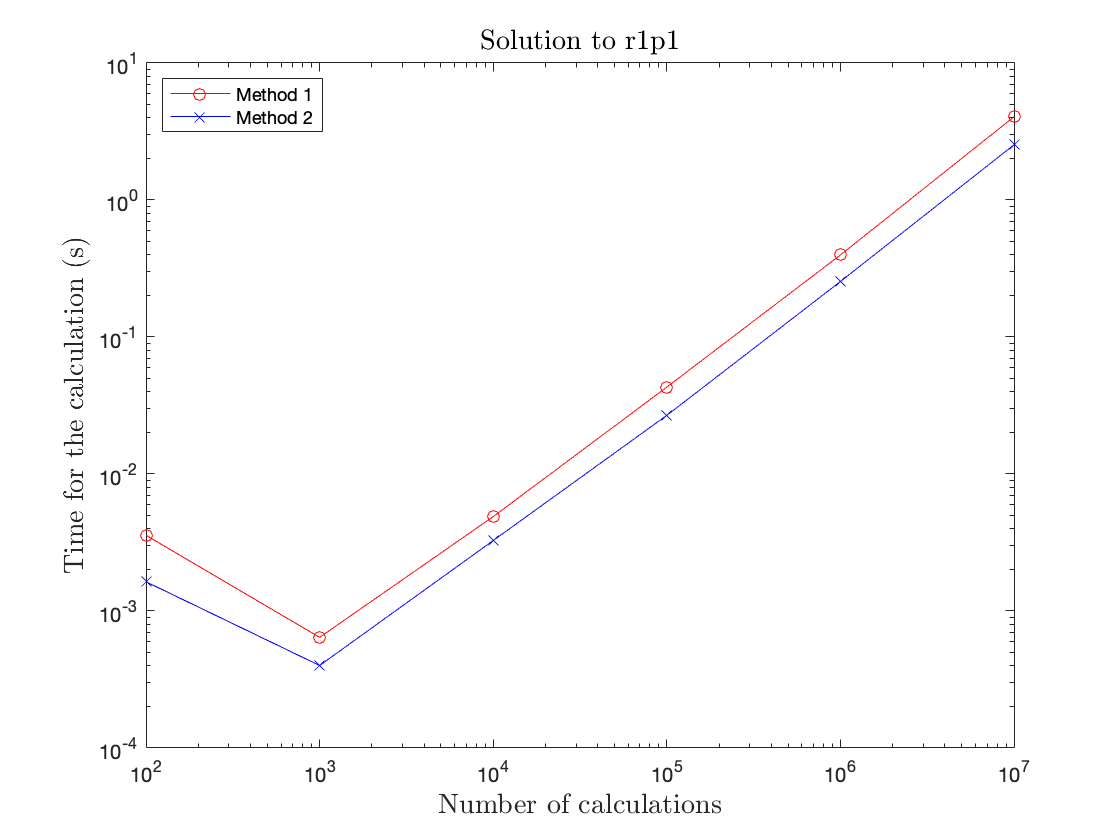

%plot
h = figure;
loglog(ncalcs, method1_times, '-or', ncalcs, method2_times, '-xb')
legend('Method 1', 'Method 2','Location','NorthWest') 
xlabel('Number of calculations','FontSize',14) 
ylabel('Time for the calculation (s)','FontSize',14) 
title('Solution to r1p1','FontSize',14)

You can clearly see that method 2 (`lj_fast`) is consistently faster than method 1 (`lj`).

function [energy] = lj(a, b)
    % LJ computes energy between two particles at positions a and b
    % from the Lennard-Jones interaction potential
    % Input: row vectors a, b
    % Output: scalar energy
    r = distance(a, b);
    energy = 1/r^12 - 1/r^6;
end

function [r] = distance(a, b)
    % DISTANCE computes distance between vectors a and b
    % Input: row vectors a, b
    % Output: scalar r
    assert(isequal(size(a), [1 3]) & isequal(size(b), [1 3]))
    d = b - a; 
    r2 = dot(d, d); %can also write this as d*(d.'
    r = sqrt(r2);
end

function [energy] = lj_fast(a, b)
    % LJ_FAST computes energy between two particles at positions a and b
    % from the Lennard-Jones interaction potential. It is fast because it
    % avoids square roots and uses fewer multiplications
    % Input: row vectors a, b
    % Output: scalar energy
    ir2 = idistance2(a, b);
    ir6 = ir2 * ir2 *ir2;
    ir12 = ir6 * ir6;
    energy = ir12 - ir6;
end

function [ir2] = idistance2(a, b)
    % IDISTANCE2 computes the inverse square distance (1/r^2) between
    % vectors a and b
    % Input: row vectors a, b
    % Output: scalar ir2
    assert(isequal(size(a), [1 3]) & isequal(size(b), [1 3]))
    d = b - a; 
    r2 = dot(d, d);  %can also write this as d*(d.')
    ir2 = 1/r2;
end